# Post processing of Steady Results.

% clear;
% clc;

% Import all data 
cd('X:\Research Project\steady\all_steady_data\');



% importing the steady data 
a1_cfx = getmydata('s1_simA_Cfx.csv');
b1_cfx = getmydata('s1_simB_Cfx.csv');
c1_cfx = getmydata('s1_simC_Cfx.csv');
d1_cfx = getmydata('s1_simD_Cfx.csv');
e1_cfx = getmydata('s1_simE_Cfx.csv');
f1_cfx = getmydata('s1_simF_Cfx.csv');
g1_cfx = getmydata('s1_simG_Cfx.csv');
h1_cfx = getmydata('s1_simH_Cfx.csv');

a1u_cfx = getmydata('u1_simA_Cfx.csv');
b1u_cfx = getmydata('u1_simB_Cfx.csv');
c1u_cfx = getmydata('u1_simC_Cfx.csv');
d1u_cfx = getmydata('u1_simD_Cfx.csv');
% e1u_cfx = getmydata('u1_simE_Cfx.csv');
% f1u_cfx = getmydata('u1_simF_Cfx.csv');
% g1u_cfx = getmydata('u1_simG_Cfx.csv');
% h1u_cfx = getmydata('u1_simH_Cfx.csv');

cd('..')
les_cfx = readmatrix('Cf-vs-xc_3.8aLES.csv');

% Finding % differences in the models 
x_c = a1_cfx(:,1);      % these are the x/c values you want LES point to be on 
x_c(:,2) = interp1(les_cfx(:,1), les_cfx(:,2), x_c(:,1));

for i=1:size(x_c,1)
a1_cfx(i,3) = (a1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
b1_cfx(i,3) = (b1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
c1_cfx(i,3) = (c1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
d1_cfx(i,3) = (d1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
e1_cfx(i,3) = (e1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
f1_cfx(i,3) = (f1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
g1_cfx(i,3) = (g1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
h1_cfx(i,3) = (h1_cfx(i,2) - x_c(i,2))*(100/x_c(i,2));
end

% average % difference 
a1_cfx(:,4) = abs(mean(a1_cfx(:,3)));
b1_cfx(:,4) = abs(mean(b1_cfx(:,3)));
c1_cfx(:,4) = abs(mean(c1_cfx(:,3)));
d1_cfx(:,4) = abs(mean(d1_cfx(:,3)));
e1_cfx(:,4) = abs(mean(e1_cfx(:,3)));
f1_cfx(:,4) = abs(mean(f1_cfx(:,3)));
g1_cfx(:,4) = abs(mean(g1_cfx(:,3)));
h1_cfx(:,4) = abs(mean(h1_cfx(:,3)));



## save steady data

save steady290.mat

## all les data load

cd('..\unsteady\LES_data\')
load lesdat.mat
cd('..\..\steady\')

load steady300.mat
load steady290.mat


col 1,2 -> init laminar

col 3,4 -> init turbulent

col 5,6 -> init transition

col 7,8 -> final laminar

col 9,10 -> final turbulent

col 11,12 -> final transition

% % reading Cf temporal data 
% cd('cf temporal reference dat\')
% init_lam = readmatrix('initial laminar.csv');
% init_turb = readmatrix('initial turbulent.csv');
% init_trans = readmatrix('initial transition.csv');
% fin_lam = readmatrix('final laminar.csv');
% fin_turb = readmatrix('final turbulent.csv');
% fin_trans = readmatrix('final transition.csv');
% cd('..')

## Initial Regime Models - 1


figure(1);
title('Cf vx x/c for different models - Steady simulation of initial regime')
hold on 
% steady
% plot(a1_cfx(:,1), a1_cfx(:,2), '*--' , MarkerSize=4 , LineWidth=2, Color ='#ff6600');  %A    % k epsilon 
plot(b1_cfx(:,1), b1_cfx(:,2), 'o--' , MarkerSize=4 , LineWidth=2, Color ='#ff00e0');   % B  % k epsilon EB
% plot(c1_cfx(:,1), c1_cfx(:,2), '+--' , MarkerSize=4 , LineWidth=2, Color ='#ff252d');   %C  % k epsilon LRe
plot(d1_cfx(:,1), d1_cfx(:,2), 'h--' , MarkerSize=3 , LineWidth=2, Color ='#9700ff');    %D  % k epsilon V2F LRe
plot(e1_cfx(:,1), e1_cfx(:,2), 'p--' , MarkerSize=3 , LineWidth=2, Color ='#2986cc');    %E % kw SST
% plot(f1_cfx(:,1), f1_cfx(:,2), 'x--' , MarkerSize=2 , LineWidth=2, Color ='#66a32f');   %F  % kw SST Gamma 
plot(g1_cfx(:,1), g1_cfx(:,2), '<--' , MarkerSize=2 , LineWidth=2, Color ='#0033fd');    %G % kw SST Gamma ReTheta
% plot(h1_cfx(:,1), h1_cfx(:,2), '.--' , MarkerSize=3 , LineWidth=1, Color ='#ff8000');   %H  % Laminar

%unsteady
% plot(a1u_cfx(:,1), a1u_cfx(:,2), '*-.' , MarkerSize=2 , LineWidth=2, Color ='#ff6600');     % k epsilon 
% plot(b1u_cfx(:,1), b1u_cfx(:,2), 'o-.' , MarkerSize=2 , LineWidth=2, Color ='#ff00e0');     % k epsilon EB
% plot(c1u_cfx(:,1), c1u_cfx(:,2), '+-.' , MarkerSize=2 , LineWidth=2, Color ='#ff252d');     % k epsilon LRe
% plot(d1u_cfx(:,1), d1u_cfx(:,2), 'h-.' , MarkerSize=2 , LineWidth=2, Color ='#9700ff');     % k epsilon V2F LRe
% plot(e1u_cfx(:,1), e1u_cfx(:,2), 'p-.' , MarkerSize=2 , LineWidth=2, Color ='#2986cc');     % kw SST
% plot(f1u_cfx(:,1), f1u_cfx(:,2), 'x-.' , MarkerSize=2 , LineWidth=2, Color ='#66a32f');     % kw SST Gamma 
% plot(g1u_cfx(:,1), g1u_cfx(:,2), '<-.' , MarkerSize=2 , LineWidth=2, Color ='#0033fd');     % kw SST Gamma ReTheta
% plot(h1u_cfx(:,1), h1u_cfx(:,2), '.-.' , MarkerSize=3 , LineWidth=1, Color ='#ff8000');     % Laminar

% LES
plot(les_cfx(:,1), les_cfx(:,2), ':', LineWidth=3, Color ='#bc0707');   % LES


% Reference values 
plot(init_lam(:,1), init_lam(:,2), ':', LineWidth=1.5 , Color='#bcbcbc')      % initial blasius
plot(init_turb(:,1), init_turb(:,2), '-.', LineWidth=1.5, Color='#bcbcbc' )      % initial turbulent
scatter(init_trans(:,1), init_trans(:,2), '^', 'filled','MarkerFaceColor','#bcbcbc')             % initial transition

%legend('Std KE', 'KE EB', 'KE LRe', 'KE V2F', 'KW SST', 'KW SST Gt', 'KW SST GReT', 'Laminar', 'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Region');
legend( 'KE EB', 'KE V2F', 'KW SST',  'KW SST GReT',  'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Region');


hold off 
xlabel('x/c')
ylabel('Cf')
ylim([0 0.015])

%BCDEG -> ones to test in the unsteady simulations
% steady results match unsteady. so, its ok. 



## Initial Regime Models % difference

figure;
title('Cf vx x/c for different models - Steady simulation of initial regime % difference')
hold on 
% steady
plot(a1_cfx(:,1), a1_cfx(:,3), '*--' , MarkerSize=3 , LineWidth=1.5, Color ='#ff6600');     % k epsilon 
plot(b1_cfx(:,1), b1_cfx(:,3), 'o--' , MarkerSize=3 , LineWidth=1.5, Color ='#ff00e0');     % k epsilon EB
plot(c1_cfx(:,1), c1_cfx(:,3), '+--' , MarkerSize=3 , LineWidth=1.5, Color ='#ff252d');     % k epsilon LRe
plot(d1_cfx(:,1), d1_cfx(:,3), 'h--' , MarkerSize=3 , LineWidth=1.5, Color ='#9700ff');     % k epsilon V2F LRe
plot(e1_cfx(:,1), e1_cfx(:,3), 'p--' , MarkerSize=3 , LineWidth=1.5, Color ='#2986cc');     % kw SST
plot(f1_cfx(:,1), f1_cfx(:,3), 'x--' , MarkerSize=3 , LineWidth=1.5, Color ='#66a32f');     % kw SST Gamma 
plot(g1_cfx(:,1), g1_cfx(:,3), '<--' , MarkerSize=3 , LineWidth=1.5, Color ='#0033fd');     % kw SST Gamma ReTheta
 plot(h1_cfx(:,1), h1_cfx(:,3), '.--' , MarkerSize=3 , LineWidth=1, Color ='#ff8000');     % Laminar
% LES
% transition region reference
temp1 = init_trans(:,1);
temp1(:,2) = -90;
scatter(temp1(:,1), temp1(:,2), '^', 'filled','MarkerFaceColor','#bcbcbc') 


% plot(les_cfx(:,1), les_cfx(:,2), ':', LineWidth=3, Color ='#bc0707');   % LES
legend('Std KE', 'KE EB', 'KE LRe', 'KE V2F', 'KW SST', 'KW SST Gt', 'KW SST GReT', 'Laminar', 'Transition Region');
hold off 
xlabel('x/c')
ylabel('Cf % difference ')



## Initial Regime mean % difference

figure(3);
title('Cf vx x/c for different models - Steady simulation of initial regime % difference')
hold on 
% steady
plot(a1_cfx(:,1), a1_cfx(:,4), '*--' , MarkerSize=2 , LineWidth=2, Color ='#ff6600');     % k epsilon 
plot(b1_cfx(:,1), b1_cfx(:,4), 'o--' , MarkerSize=2 , LineWidth=2, Color ='#ff00e0');     % k epsilon EB
plot(c1_cfx(:,1), c1_cfx(:,4), '+--' , MarkerSize=2 , LineWidth=2, Color ='#ff252d');     % k epsilon LRe
plot(d1_cfx(:,1), d1_cfx(:,4), 'h--' , MarkerSize=2 , LineWidth=2, Color ='#9700ff');     % k epsilon V2F LRe
plot(e1_cfx(:,1), e1_cfx(:,4), 'p--' , MarkerSize=2 , LineWidth=2, Color ='#2986cc');     % kw SST
plot(f1_cfx(:,1), f1_cfx(:,4), 'x--' , MarkerSize=2 , LineWidth=2, Color ='#66a32f');     % kw SST Gamma 
plot(g1_cfx(:,1), g1_cfx(:,4), '<--' , MarkerSize=2 , LineWidth=2, Color ='#0033fd');     % kw SST Gamma ReTheta
plot(h1_cfx(:,1), h1_cfx(:,4), '.--' , MarkerSize=3 , LineWidth=1, Color ='#ff8000');     % Laminar
% LES
% plot(les_cfx(:,1), les_cfx(:,2), ':', LineWidth=3, Color ='#bc0707');   % LES
legend('Std KE', 'KE EB', 'KE LRe', 'KE V2F', 'KW SST', 'KW SST Gt', 'KW SST GReT', 'Laminar', 'LES');
hold off 
xlabel('x/c')
ylabel('Cf % difference ')





## Comparison of 290 and 300 - kwsst and LES and log linear data

model = steady300

plot(model(:,1) , model(:,3), '-', 'LineWidth', 2)   % kw

plot(model(:,1) , model(:,4), '-', 'LineWidth', 2)   % kw sst ReTheta

plot(model(:,1) , model(:,5), '-', 'LineWidth', 2)   % kw sst low Re damping

plot(model(:,1) , model(:,6), '-', 'LineWidth', 2)   % ke

plot(model(:,1) , model(:,7), '-', 'LineWidth', 2)   % sa

figure();

hold on
% k epsilon 
% plot(steady300(:,1), steady300(:,6), '--' , MarkerSize=2 , LineWidth=2, Color ='#ff6600')   % 300
% plot(a1_cfx(:,1), a1_cfx(:,2), '*--' , MarkerSize=4 , LineWidth=2, Color ='#ff6600');     % 290

% k omega sst gamma retheta
plot(steady300(:,1), steady300(:,4), 'g--' , MarkerSize=2 , LineWidth=2) % 300
plot(g1_cfx(:,1), g1_cfx(:,2), '<--' , MarkerSize=2 , LineWidth=2, Color ='#0033fd');     % 290

% LES
plot(les_cfx(:,1), les_cfx(:,2), ':', LineWidth=3, Color ='#bc0707');   % LES

% Reference values 
plot(init_lam(:,1), init_lam(:,2), ':', LineWidth=1.5 , Color='#bcbcbc')      % initial blasius
plot(init_turb(:,1), init_turb(:,2), '-.', LineWidth=1.5, Color='#bcbcbc' )      % initial turbulent

scatter(init_trans(:,1), init_trans(:,2), '^', 'filled','MarkerFaceColor','#bcbcbc')             % initial transition

hold off

title('Cf vs x for 300K and 290K KW SST GReTheta')
xlabel('x/c')
ylabel('Cf - Skin Friction Coefficient')
ylim([0 0.015])

%legend('KE, T1 = 300K', 'KE, T1 = 290K', 'KW SST GReTheta, T1 = 300K', 'KW SST GReT, T1 = 290K', 'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Solution')
legend('T1 = 300K','T1 = 290K', 'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Solution')






## final regime Cf

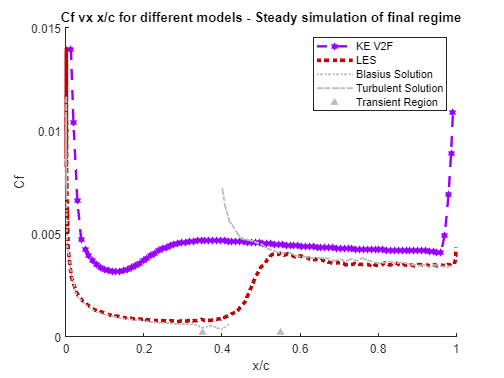

figure(1);
title('Cf vx x/c for different models - Steady simulation of final regime')
hold on 
% steady

% plot(p_pltB(:,1,size(p_pltB,1)), p_pltB(:,4,size(p_pltB,1)), 'o--' , MarkerSize=4 , LineWidth=2, Color ='#ff00e0');   % B  % k epsilon EB
plot(p_pltD(:,1,size(p_pltD,1)), p_pltD(:,4,size(p_pltD,1)), 'h--' , MarkerSize=3 , LineWidth=2, Color ='#9700ff');    %D  % k epsilon V2F LRe
% plot(p_pltE(:,1,size(p_pltE,1)), p_pltE(:,4,size(p_pltE,1)), 'p--' , MarkerSize=3 , LineWidth=2, Color ='#2986cc');    %E % kw SST
% plot(p_pltG(:,1,size(p_pltG,1)), p_pltG(:,4,size(p_pltG,1)), '<--' , MarkerSize=2 , LineWidth=2, Color ='#0033fd');    %G % kw SST Gamma ReTheta


% LES
plot(cfx_f_les(:,1), cfx_f_les(:,2), ':', LineWidth=3, Color ='#bc0707');   % LES


% Reference values 
plot(fin_lam(:,1), fin_lam(:,2), ':', LineWidth=1.5 , Color='#bcbcbc')      % initial blasius
plot(fin_turb(:,1), fin_turb(:,2), '-.', LineWidth=1.5, Color='#bcbcbc' )      % initial turbulent
scatter(fin_trans(:,1), fin_trans(:,2), '^', 'filled','MarkerFaceColor','#bcbcbc')             % initial transition

%legend('Std KE', 'KE EB', 'KE LRe', 'KE V2F', 'KW SST', 'KW SST Gt', 'KW SST GReT', 'Laminar', 'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Region');
% legend( 'KE EB', 'KE V2F', 'KW SST',  'KW SST GReT',  'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Region');
legend('KE V2F', 'LES', 'Blasius Solution', 'Turbulent Solution', 'Transient Region');


hold off 
xlabel('x/c')
ylabel('Cf')
ylim([0 0.015])

function output_matrix = getmydata(file_name)
temp = readmatrix(file_name);
temp = sortrows(temp,1);
output_matrix = temp(:,(1:2));
end